clear all; close all; clc
filename = 'FH_Ne.xlsx';
num_sheets = 4; % Número total de hojas

% Crea matrices vacías para almacenar los datos
data_matrices = cell(num_sheets, 1);

for sheet = 1:num_sheets
    % Lee los datos de la hoja actual
    [~, ~, raw_data] = xlsread(filename, sheet);
    
    % Filtra solo los valores numéricos de las columnas A y B
    numeric_data = [];
    for row = 1:size(raw_data, 1)
        % Verifica si el contenido de la celda es numérico
        if isnumeric(raw_data{row, 1}) && isnumeric(raw_data{row, 2})
            % Agrega los valores numéricos a la matriz
            numeric_data = [numeric_data; raw_data{row, 1}, raw_data{row, 2}];
        end
    end
    
    % Eliminar las entradas NaN de la matriz
    numeric_data = numeric_data(~any(isnan(numeric_data), 2), :);
    
    % Almacena los datos en una matriz
    data_matrices{sheet} = numeric_data;
end

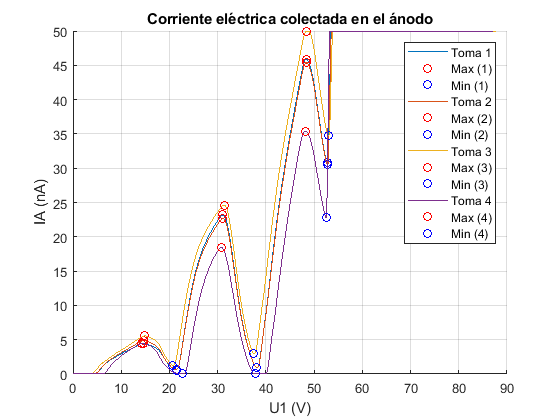

figure;
hold on;

colors = lines(num_sheets); % Generar colores distintos

% Vectores para almacenar los valores de los picos máximos y mínimos
max_peak_values = [];
max_peak_x_values = [];
min_peak_values = [];
min_peak_x_values = [];

for sheet = 1:num_sheets
    % Obtener la matriz actual
    numeric_data = data_matrices{sheet};
    
    % Extraer las columnas X y Y
    x = numeric_data(:, 1);
    y = numeric_data(:, 2);
    
    % Encontrar los picos máximos utilizando la prominencia mínima
    [~, max_peak_indices] = findpeaks(y, 'MinPeakProminence', 0.2); % Ajusta el valor de la prominencia mínima según tus necesidades
    
    % Eliminar picos máximos cercanos en el eje X
    max_peak_indices = remove_close_peaks(x, max_peak_indices);
    
    % Guardar los valores de los picos máximos y sus correspondientes valores en x
    max_peak_values = [max_peak_values; y(max_peak_indices)];
    max_peak_x_values = [max_peak_x_values; x(max_peak_indices)];
    
    % Encontrar los picos mínimos utilizando la prominencia mínima
    [~, min_peak_indices] = findpeaks(-y, 'MinPeakProminence', 0.2); % Ajusta el valor de la prominencia mínima según tus necesidades
    
    % Eliminar picos mínimos cercanos en el eje X
    min_peak_indices = remove_close_peaks(x, min_peak_indices);
    
    % Guardar los valores de los picos mínimos y sus correspondientes valores en x
    min_peak_values = [min_peak_values; y(min_peak_indices)];
    min_peak_x_values = [min_peak_x_values; x(min_peak_indices)];
    
    % Graficar los datos con un color único
    plot(x, y, 'Color', colors(sheet, :));
    
    % Mostrar los picos máximos en la gráfica
    plot(x(max_peak_indices), y(max_peak_indices), 'ro');
    
    % Mostrar los picos mínimos en la gráfica
    plot(x(min_peak_indices), y(min_peak_indices), 'bo');
end

% Personalizar el aspecto de la gráfica
xlabel('U1 (V)');
ylabel('IA (nA)');
title('Corriente eléctrica colectada en el ánodo');
legend('Toma 1', 'Max (1)', 'Min (1)', 'Toma 2', 'Max (2)', 'Min (2)', 'Toma 3', 'Max (3)', 'Min (3)', 'Toma 4', 'Max (4)', 'Min (4)');
grid on

hold off;

min_I_Ne = (reshape(min_peak_x_values,[],4))'

min_I_Ne =    21.3900   38.1400   52.7400
   21.3600   38.0900   52.7700
   20.7300   37.5000   53.0100
   22.6800   37.7500   52.4700


Eexc1_Ne = diff(min_I_Ne')'

Eexc1_Ne =    16.7500   14.6000
   16.7300   14.6800
   16.7700   15.5100
   15.0700   14.7200


mean_Eexc_Ne = mean(Eexc1_Ne)

mean_Eexc_Ne =    16.3300   14.8775


Err_Eexc_Ne = std(Eexc1_Ne)

Err_Eexc_Ne =     0.8402    0.4246


function peak_indices = remove_close_peaks(x, peak_indices)
    % Eliminar picos cercanos en el eje X
    threshold_distance = 1; % Ajusta el umbral de distancia según tus necesidades
    
    % Calcular las diferencias de distancia entre picos
    peak_distances = diff(x(peak_indices));
    
    % Obtener los índices de los picos a mantener
    keep_indices = [1; find(peak_distances > threshold_distance) + 1];
    
    % Filtrar los picos cercanos
    peak_indices = peak_indices(keep_indices);
end
